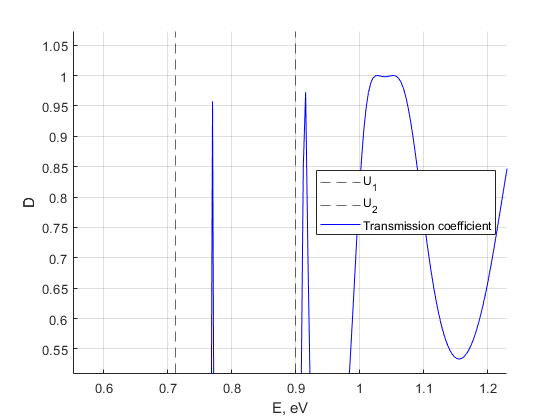

clear all; close all; clc;

% Initial data
load constants.mat; %file with constants
N=3; % The number of layers excluding the outer areas (ODD)
% Number of points n recommended
if N==1
    n=100;
elseif N==3
    n=300;
elseif N==5
    n=620;
end
x=zeros(1,N+2); % the proportion of aluminum in the compound Al(x)Ga(1-x)As
Eg=zeros(1,N+2); % Bandgap Energy
U=zeros(1,N+2); % Barrier height
meff=zeros(1,N+2);% effective mass

% The structure GaAs/Al(0,3)Ga(0,7)As/GaAs
a0=zeros(1,N); % lattice constant
a=zeros(1,N); % the thickness of the barrier, m
for j=1:N
    M=3; % width of the j-th layer in atomic monolayers (excluding external ones)
    if mod(j,2)==0
       x(:,j)=0; % for GaAs
    else
       x(:,j)=0.3; % for AlGaAs
    end
    a0(:,j)=(0.565334+0.00078*x(:,j))*1e-9;
    a(:,j)=a0(:,j)*M;
end

for j=1:N+2
    if mod(j,2)==0
        x(:,j)=0.3; % для AlGaAs
    else
        x(:,j)=0; % для GaAs 
    end
    Eg(:,j)=(1.424+1.247*x(:,j))*eV2J; % Bandgap Energy of j-th area, T=300К
    meff(:,j)=(0.067+0.083*x(:,j))*m0;
    U(:,j)=Eg(:,j)/2;
end
E=linspace(U(:,1),2*U(:,2), n); % the energy range
g=zeros(length(E), N+2); % gamma
for n=1:length(E)
    for j=1:N+2
        g(n,j)=sqrt(2*meff(:,j).*(E(n)-U(:,j))./hbar^2);
    end
end

% TRANSFER MATRIX METHOD

Tk = zeros([2 2 length(E)]); % from k layer to k+1
Z=zeros(1,N+1); % the coordinate of the j-th border
for n = 1:length(E)
    Z(:,1)=0;
    T(:,:,n)=diag([1 1]);  
    for k=1:N+1
        Tk(:, :, n) = 1/2*[(1 + g(n,k)./g(n,k+1).*meff(:,k+1)./meff(:,k)).*exp(-i*(g(n,k+1) - g(n,k)).*Z(:,k)), (1 - g(n,k)./g(n,k+1).*meff(:,k+1)./meff(:,k)).*exp(-i*(g(n,k+1) + g(n,k)).*Z(:,k));
            (1 - g(n,k)./g(n,k+1).*meff(:,k+1)./meff(:,k)).*exp(i*(g(n,k+1) + g(n,k)).*Z(:,k)), (1 +g(n,k)./g(n,k+1).*meff(:,k+1)./meff(:,k)).*exp(i*(g(n,k+1) - g(n,k)).*Z(:,k))];
        if k<N+1
            Z(:,k+1)=Z(:,k)+a(:,k);
        end
        T(:,:,n) = Tk(:,:,n)*T(:,:,n); % the transfer matrix across the whole structure
    end
end

% find the coefficients of the transfer matrix through the whole structure
% (dimensions 1x1x100 into 1x100)
T00 = reshape(T(1,1,:), 1, length(E));
T01 = reshape(T(1,2,:), 1, length(E));
T10 = reshape(T(2,1,:), 1, length(E));
T11 = reshape(T(2,2,:), 1, length(E));

% Transmission coefficient
D=abs(g(:,N+2))./abs(g(:,1)).*meff(:,1)./meff(:,N+2).*abs((T11.*T00-T01.*T10)./T11).^2;
D=diag(D);

% Reflection coefficient
R=abs(T10./T11).^2;

% Graphics
hold on;
grid on;
xline(gca, U(1)*J2eV,"LineStyle","--");
xline(gca, U(2)*J2eV,"LineStyle","--");
plot(E*J2eV, D,"b");
%plot(E*J2eV, R,"r");
legend("U_1","U_2","Transmission coefficient", "Location",'east');
xlabel("E, eV");
ylabel("D");
hold off;

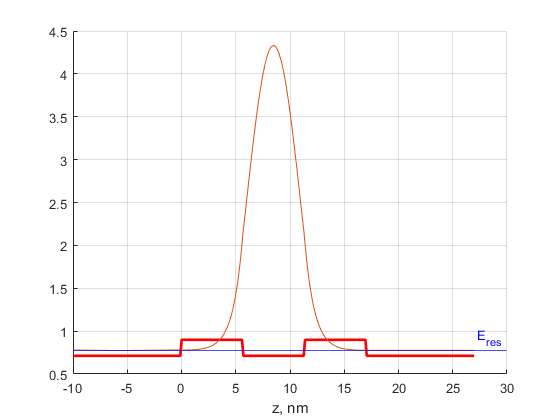


% Construction of the envelopes of the WF

Afirst=ones(1,length(E)); % before the barrier
Bfirst = -T10./T11.*Afirst; % before the barrier
Alast = (T11.*T00-T01.*T10)./T11.*Afirst; % after the barrier
if N==1
    A1=0.18*Afirst;
else
    A1=0.08*Afirst;
end
B1 = A1.*Bfirst;
A_N = A1.*Alast;
Psi=zeros(2,length(E),N+2);
Psi(:,:,1)=[A1; B1]; % coefficients of the psi-function before the barrier
Tk = zeros([2 2 length(E)]);
for n=1:length(E)
    for k=1:N
        Tk(:, :, n) = 1/2*[(1 + g(n,k)./g(n,k+1).*meff(:,k+1)./meff(:,k)).*exp(-i*(g(n,k+1) - g(n,k)).*Z(:,k)), (1 - g(n,k)./g(n,k+1).*meff(:,k+1)./meff(:,k)).*exp(-i*(g(n,k+1) + g(n,k)).*Z(:,k));
        (1 - g(n,k)./g(n,k+1).*meff(:,k+1)./meff(:,k)).*exp(i*(g(n,k+1) + g(n,k)).*Z(:,k)), (1 +g(n,k)./g(n,k+1).*meff(:,k+1)./meff(:,k)).*exp(i*(g(n,k+1) - g(n,k)).*Z(:,k))];
        Psi(:,n,k+1)=Tk(:,:,n)*Psi(:,n,k); % coefficients of the psi-function inside the structure
    end
end
Psi(:,:,N+2)=[A_N; zeros(1, length(E))]; % coefficients of the psi-function after the barrier

z1=Z(:,1)-1e-8;
z2=Z(:,N+1)+1e-8;
z=linspace(z1,z2, length(E)); % the length range
Nz=size(z,2);
psi=zeros(Nz,length(E),N+2);
for n=1:length(E)
    for j=1:N+2
            psi(:,n,j)=(abs(Psi(1,n,j)*exp(i*g(n,j).*z)+Psi(2,n,j)*exp(-i*g(n,j).*z))).^2; % psi-function in the j-th area
    end
end

V=zeros(1,Nz); % potential structure
PSI=zeros(Nz,length(E)); % psi-function depending on the coordinate
for t=1:Nz
     if z(t)<Z(1)
        j=1;
        V(t)=U(j)*J2eV;
        PSI(t,:)=psi(t,:,j);
    elseif z(t)>=Z(N+1)
        j=N+2;
        V(t)=U(j)*J2eV;
        PSI(t,:)=psi(t,:,j);
    end
    for j=2:N+1
        if (z(t)>=Z(j-1))&&(z(t)<Z(j))
            V(t)=U(j)*J2eV;
            PSI(t,:)=psi(t,:,j);
        end
    end
end
E=E*J2eV;
z=z*1e9;
Pks_max = islocalmax(D); % find local maxima
Epks=E(Pks_max);
ind=find(Pks_max);
l=0;
for k=1:length(Epks)
    if Epks(k)<=U(2)*J2eV
        Eres=Epks(k);
        figure;
        grid on;
        hold on;
        plot(z,V, 'r',"LineWidth", 2);
        plot(z, PSI(:, ind(k))+Eres);
        yline(Eres, 'b-', 'E_r_e_s');
        xlabel('z, nm');
        l=l+1;
    end
end

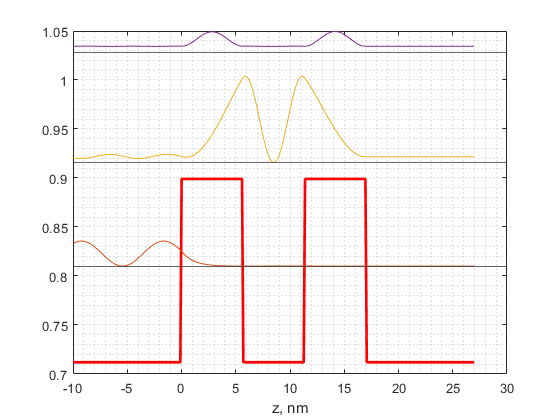

[U2, ind2]=min(abs(E-0.9*U(2)*J2eV));
figure;
plot(z,V, 'r',"LineWidth", 2);
hold on;
grid("minor")
plot(z, PSI(:, ind2)+E(ind2));
yline(E(ind2));
plot(z, PSI(:, ind(l+1))+Epks(l+1));
yline(Epks(l+1));
plot(z, PSI(:, ind(l+2))+Epks(l+2));
yline(Epks(l+2));
xlabel('z, nm');